# Exercise 2 regbot

## Plot data from the log txt file

% Read data from the log.txt file using readtable() function
% data = readtable('C:\Users\Alonso\Desktop\log_01.txt','FileType','text') %creates a table by reading column oriented data from a file.
% data = readtable('C:\Users\Alonso\Desktop\log.txt','FileType','text') %creates a table by reading column oriented data from a file.
%data = readtable(['log.txt']) % it loads the data in a table struct
data = readtable('C:\Users\Alonso\Desktop\REGBOT\Ex_2_calib\regbot_log_2.txt')

data = 1118×15 table
    Var1     Var2    Var3    Var4    Var5    Var6    Var7    Var8    Var9    Var10    Var11    Var12    Var13    Var14    Var15 
    _____    ____    ____    ____    ____    ____    ____    ____    ____    _____    _____    _____    _____    _____    ______

    0.002     2       1       0       0       0       0       0       0        0        0        0        0        0      2.9424
    0.005     2       1       0       0       0       0       0       0        0 

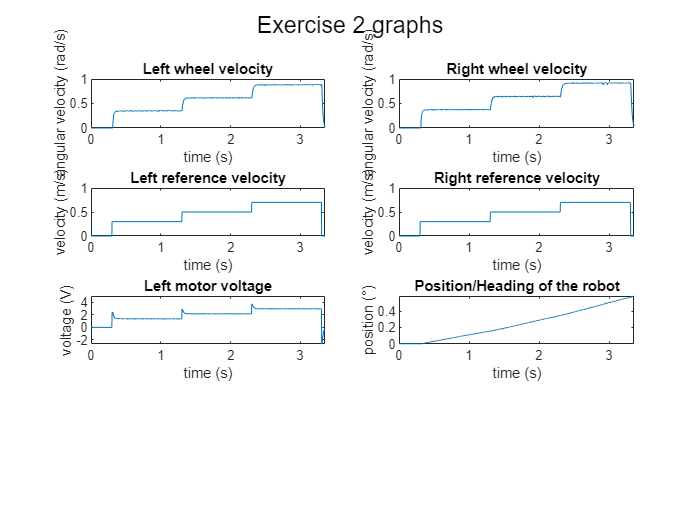

%Is there a difference with and whitout the [] ?

left_motor_voltage = 8;     %left motor voltage column
right_motor_voltage = 9;    %right motor voltage column
left_motor_velocity_ref = 6;   %left motor velocity ref
right_motor_velocity_ref = 7;    %right motor velocity ref
left_motor_velocity = 10;     %left motor velocity 
right_motor_velocity = 11;     %right motor velocity
pose_heading = 14;  %heading/direction of the robot

% fill the NaN entries using the fillmissing() function
data = fillmissing(data, 'nearest');
% Convert data from a table to a matrix using the table2array() function

% Create matrix t for time stamps
t = table2array(data(:, 1));
% Create matrix ul for left motor voltage 
l_u = table2array(data(:, left_motor_voltage));
% Check the right column in the log.txt
% Create matrix ur for right motor voltage
r_u = table2array(data(:, right_motor_voltage));
% Create matrix vrl for left motor velocity ref
l_v_ref = table2array(data(:, left_motor_velocity_ref));
% Create matrix vrr for right motor velocity ref
r_v_ref = table2array(data(:, right_motor_velocity_ref));
% Create matrix wl for left motor velocity
l_v = table2array(data(:, left_motor_velocity));
% Create matrix wr for right motor velocity
r_v = table2array(data(:, right_motor_velocity));
% Create matrix wr for right motor velocity
pose_h = table2array(data(:, pose_heading));


% Create a figure
figure(5);
% Create a subplot and plot the left wheel velocity wl - remind to define axis labels and title
subplot(4,2,1);
plot(t, l_v)
xlim([0 t(end)])
ylim([0 1])
xlabel('time (s)')
ylabel('angular velocity (rad/s)')
title('Left wheel velocity')

% Create a subplot and plot the right wheel velocity wr - remind to define axis labels and title
subplot(4,2,2);
plot(t, r_v)
xlim([0 t(end)])
ylim([0 1])
xlabel('time (s)')
ylabel('angular velocity (rad/s)')
title('Right wheel velocity')

% Create a subplot and plot the left wheel reference velocity vrl
subplot(4,2,3);
plot(t, l_v_ref)
xlim([0 t(end)])
ylim([0 1])
xlabel('time (s)')
ylabel('velocity (m/s)')
title('Left reference velocity')

% Create a subplot and plot the right wheel reference velocity vrr
subplot(4,2,4);
plot(t, r_v_ref)
xlim([0 t(end)])
ylim([0 1])
xlabel('time (s)')
ylabel('velocity (m/s)')
title('Right reference velocity')

% Create a subplot and plot the left wheel voltage ul - remind to define axis labels and title
subplot(4,2,5);
plot(t, l_u)
xlim([0 t(end)])
xlabel('time (s)')
ylabel('voltage (V)')
title('Left motor voltage')

% Create a subplot and plot the left wheel voltage ur - remind to define axis labels and title
subplot(4,2,6);
plot(t, r_u)
xlim([0 t(end)])
xlabel('time (s)')
ylabel('voltage (V)')
title('Right motor voltage')

% Create a subplot and plot the POs/heading
subplot(4,2,6);
plot(t, pose_h)
xlim([0 t(end)])
xlabel('time (s)')
ylabel('position (°)')
title('Position/Heading of the robot')

% Add a title to the whole figure
sgtitle('Exercise 2 graphs')